%% 基础参数定义
geom.L = 24e-6;
geom.w = 1e-6;
geom.t = 0.2e-6;

mat.E  = 1.9e13;
def.y0 = 8e-6;

%% 截面惯性矩（通过匿名函数计算）
calcI = @(w,t) w .* t.^3 ./ 12;
Izz = calcI(geom.w, geom.t);

%% 等效应力与载荷计算（拆解公式）
coef1 = mat.E * def.y0;
coef2 = geom.t / geom.L^2;

sigma_bend = (3/2) * coef1 * coef2;

% 利用梁挠度反推载荷
calcF = @(E,I,y,L) (E.*I.*y) ./ (L.^3) * 3;
F_est = calcF(mat.E, Izz, def.y0, geom.L);

% 另一种应力表达
sigma_alt = 6 * F_est * geom.L / (geom.w * geom.t^2);

%% 几何关系
theta_val = asin(def.y0 / (0.85 * geom.L));
x_tip = geom.L * (0.15 + 0.85*cos(theta_val));

%% 等效刚度模型
kappa = @(E,I,L,theta) 2.25 * E .* I .* theta ./ (L.^2);
F_nl = kappa(mat.E, Izz, geom.L, theta_val) ./ (0.85*cos(theta_val));



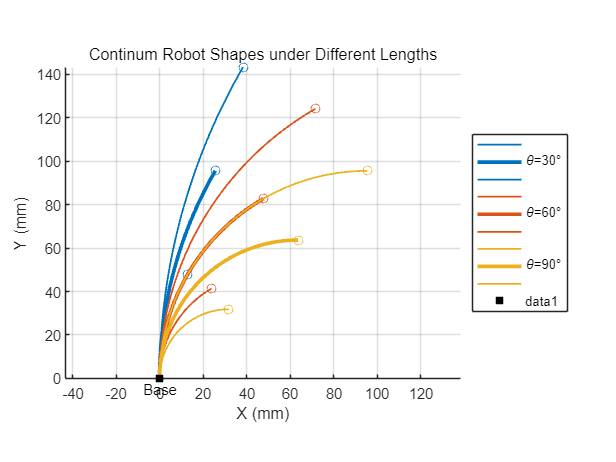

clc; clear; close all;

%% 参数组
L_set = [50, 100, 150];
theta_set = deg2rad([30 60 90]);

figure('Color','w'); hold on;
axis equal; grid on;

cmap = lines(numel(theta_set));

%% 主循环
for i = 1:numel(theta_set)
    th = theta_set(i);

    % 末端轨迹（射线）
    L_range = linspace(min(L_set), max(L_set), 80);
    x_ray = (L_range./th).*(1-cos(th));
    y_ray = (L_range./th).*sin(th);
    plot(x_ray, y_ray, ':', 'Color',[.6 .6 .6]);

    % 三个长度下的形态
    for j = 1:numel(L_set)
        Lc = L_set(j);
        R = Lc / th;

        s = linspace(0, th, 60);
        xs = R*(1-cos(s));
        ys = R*sin(s);

        if Lc == 100
            lw = 2.5;
            nameStr = sprintf('\\theta=%d°', round(rad2deg(th)));
        else
            lw = 1.2;
            nameStr = '';
        end

        plot(xs, ys, 'LineWidth', lw, ...
            'Color', cmap(i,:), 'DisplayName', nameStr);

        plot(xs(end), ys(end), 'o', ...
            'Color', cmap(i,:), 'HandleVisibility','off');
    end
end

xlabel('X (mm)');
ylabel('Y (mm)');
title('Continum Robot Shapes under Different Lengths');
legend('Location','eastoutside');

plot(0,0,'ks','MarkerFaceColor','k');
text(0,-5,'Base','HorizontalAlignment','center');